clc;
clear;
close all;
addpath("utils\")

## 0.Defined Function

l1 = 1;
l2 = 2;
m1 = 5;
m2 = 5;
B1 = 2;
B2 = 2;
g = 9.81;

k = 1.2*pi;

Mr = 3.6*100;
vr = 3000/100;
v12 = vr * 6;

## 1.Simulation

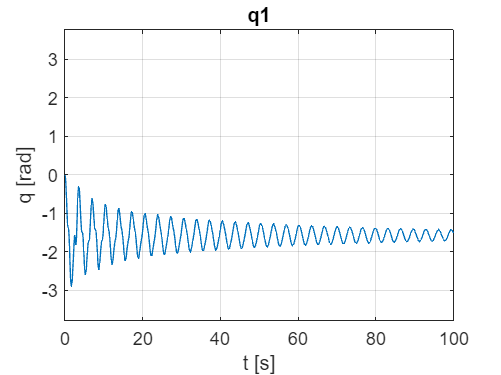

simTime = 100;
sim1 = sim("rob_zadanie2_sim1.slx", 'StopTime', num2str(simTime));

figure;
plot(sim1.tout,sim1.q1)
grid on;
title('q1');
ylim([-k, k]);
xlabel('t [s]');
ylabel('q [rad]');

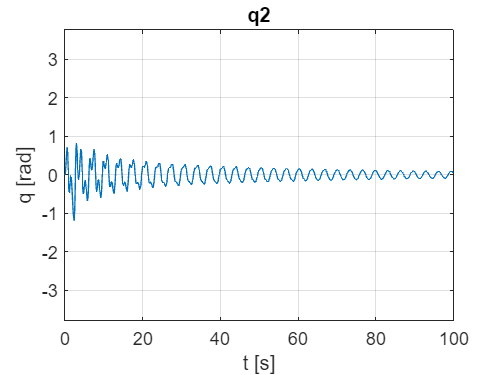


figure;
plot(sim1.tout,sim1.q2)
grid on;
title('q2');
ylim([-k, k]);
xlabel('t [s]');
ylabel('q [rad]');

## 2.Defined Function

maxq = ones(1,60)*3

maxq =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


maxM = ones(1,60)*Mr

maxM =    360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360   360


z1 = [0 1/2 0.9 -0.9 1/2 0]*pi;
z2 = [0 0.9 1/2 0 -0.9 0]*pi;
t = 0:10:50;
q1z = transpose([t;z1])

q1z =          0         0
   10.0000    1.5708
   20.0000    2.8274
   30.0000   -2.8274
   40.0000    1.5708
   50.0000         0


q2z = transpose([t;z2])

q2z =          0         0
   10.0000    2.8274
   20.0000    1.5708
   30.0000         0
   40.0000   -2.8274
   50.0000         0


## 3.PID

% Starting positions
sp1 = -1/2*pi;
sp2 = 0;
N = 250;
% PID 1
P1 = 3400;
I1 = 40;
D1 = 1800;
N1 = N;

% PID 2
P2 = 2000;
I2 = 60;
D2 = 1200;
N2 = N;

## 4.Simulation

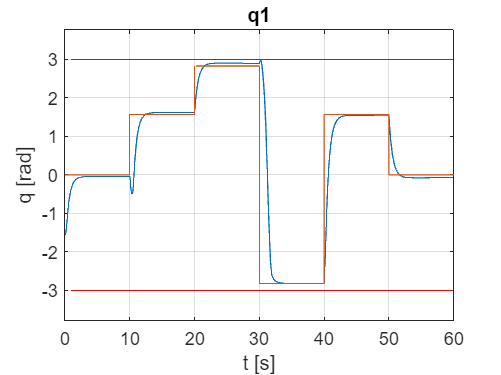

simTime = 60;
sim2 = sim("rob_zadanie2_sim2.slx", 'StopTime', num2str(simTime));

figure;
plot(sim2.tout,sim2.q1)
hold on;
plot(sim2.tout,sim2.q1z)
plot(maxq,'Color','red')
plot(-maxq,'Color','red')
grid on;
title('q1');
ylim([-k, k]);
xlabel('t [s]');
ylabel('q [rad]');

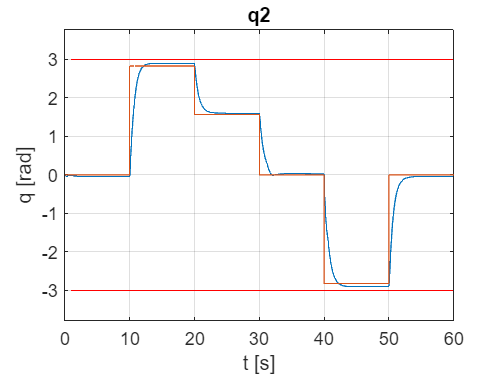


figure;
plot(sim2.tout,sim2.q2)
hold on;
plot(sim2.tout,sim2.q2z)
plot(maxq,'Color','red')
plot(-maxq,'Color','red')
grid on;
title('q2');
ylim([-k, k]);
xlabel('t [s]');
ylabel('q [rad]');

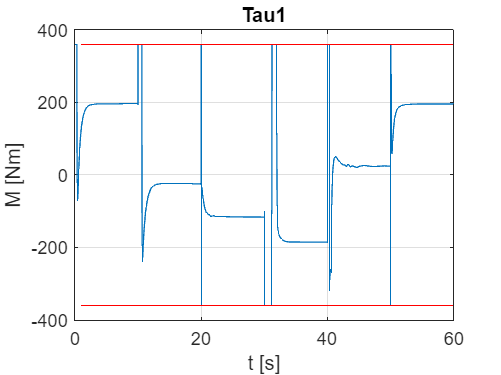


figure;
plot(sim2.tout,sim2.Tau1)
hold on;
plot(maxM,'Color','red')
plot(-maxM,'Color','red')
grid on;
title('Tau1');
xlabel('t [s]');
ylabel('M [Nm]');

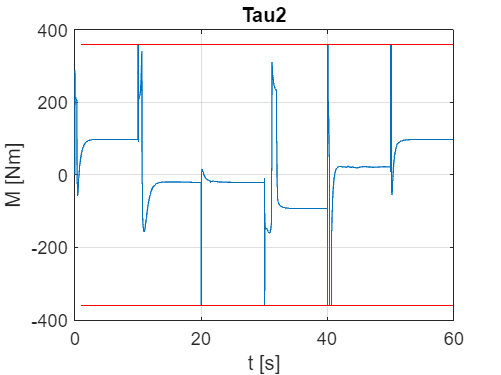


figure;
plot(sim2.tout,sim2.Tau2)
hold on;
plot(maxM,'Color','red')
plot(-maxM,'Color','red')
grid on;
title('Tau2');
xlabel('t [s]');
ylabel('M [Nm]');